# **Depth - Dependent Scattering Simulation**


clear; clc; close all;


## Parameters Definition

% --- MLTWA INPUT SETTINGS ---
% file_real_data  = 'MLTWA_Visso.mat';     % Your observed data file
% compare_with_data = true; % Set to false if you only want the theoretical MC model and no MLTWA input

use_table_results = false; % Set to true to use MLTWA table, false for manual input
target_frequency  = 1.5;   % Frequency to extract if use_table_results is true
file_table        = 'Final_Table_B0_Le.txt'; %

% Automatically load resultsTable if requested and not in workspace
if use_table_results && ~exist('resultsTable', 'var')
    if exist(file_table, 'file')
        % Leggiamo la tabella specificando che i delimitatori sono tabulazioni o spazi
        resultsTable = readtable(file_table, 'Delimiter', 'tab', 'VariableNamingRule', 'preserve');
    else
        error('Il file %s non esiste nella cartella corrente!', file_table);
    end
end

if use_table_results && exist('resultsTable', 'var')
    [p.etai, p.g0] = get_mltwa_parameters(resultsTable, target_frequency);
else
    % Manual Input (default values)
    p.etai  = 0.025;    % Intrinsic Attenuation
    p.g0    = 0.025;     % Scattering Coefficient (eta_s)
end
% --- Simulation Core Parameters ---%
p.Npart = 1500000;    % At least 1500000 particles 
p.dt    = 0.2;        % Time step (s) 
p.tmax  = 100;      % Max duration (s) 

% 2. Source and Geometry
p.xs = 0; p.ys = 0;   % Epicenter
p.zs = 10;            % Source depth  
p.deltar = 0.7;       % Delta x (thickness/width) 

% Velocity (depth-dependent - velocity for each layer)
p.A0 = 3.5;      %3.45     
p.A1 = 3.5;      %3.45
p.A2 = 4.6;      %4.6

% Scattering (depth-dependent - scattering for each layer)
p.g1 = p.g0;   % it can also be different from g0!
p.g2 = 0;      % for the mantle, g = 0      

p.aa1 = 0;          % First step in depth
p.aa2 = 40;         % First step in depth (example - depth of Moho)

p.b1 = 0;           % Gradient first step
p.b2 = 5;           % Gradient second step 

% Distance definition (km)
dists_vec = [10, 20, 30, 50, 75]; 
% dists_vec = 5:5:80;


file_random_input = 'random_math.dat'; % input random values for scattering - please unzip in your folder!
file_data_raw  = 'scattering.dat'; % output scattering
file_histogram   = 'histo_toro.dat';   % output histogram / input plot  

## Phase 1: Scattering Simulation

In case you prefer to run for a single layer, you can use the code scattering_function. For the multiple layer/depth-dependence however you should use the default function scattering_layer.

fprintf('--- PHASE 1: Scattering ---\n');

--- PHASE 1: Scattering ---


V2 (Multiple Layers): Generating theoretical model plot...


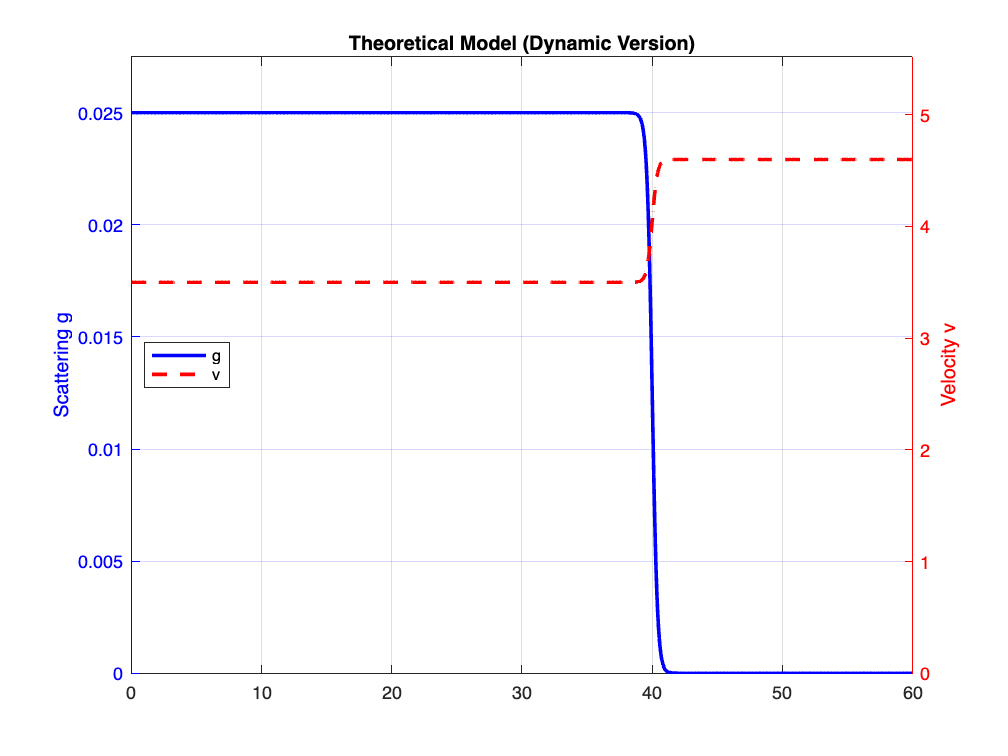

tic;

n_reflection = scattering_layer(p, file_random_input, file_data_raw);


fprintf('Scattering completed in %.2f s. Total reflections: %d\n', toc, n_reflection);

Scattering completed in 109.55 s. Total reflections: 7192292


## Phase 2: Histogram Creation and Energies Simulations

Histogram from where we obtain the energies for each distance. You can choose between two different geometries: 

1) 'toroidal' -  Toroidal volume around the symmetry axis

2) 'strip' - Spherical strip/shell around the source

fprintf('--- PHASE 2: Histogram Creation ---\n');

--- PHASE 2: Histogram Creation ---


histogram_toro(p, dists_vec, file_data_raw, file_histogram); %toroidal

Histogram saved to: histo_toro.dat



%histogram_strip(p, dists_vec, file_data_raw, file_histogram); % strip


We can plot the obtained theoretical energies with the observed events (in case we have them)

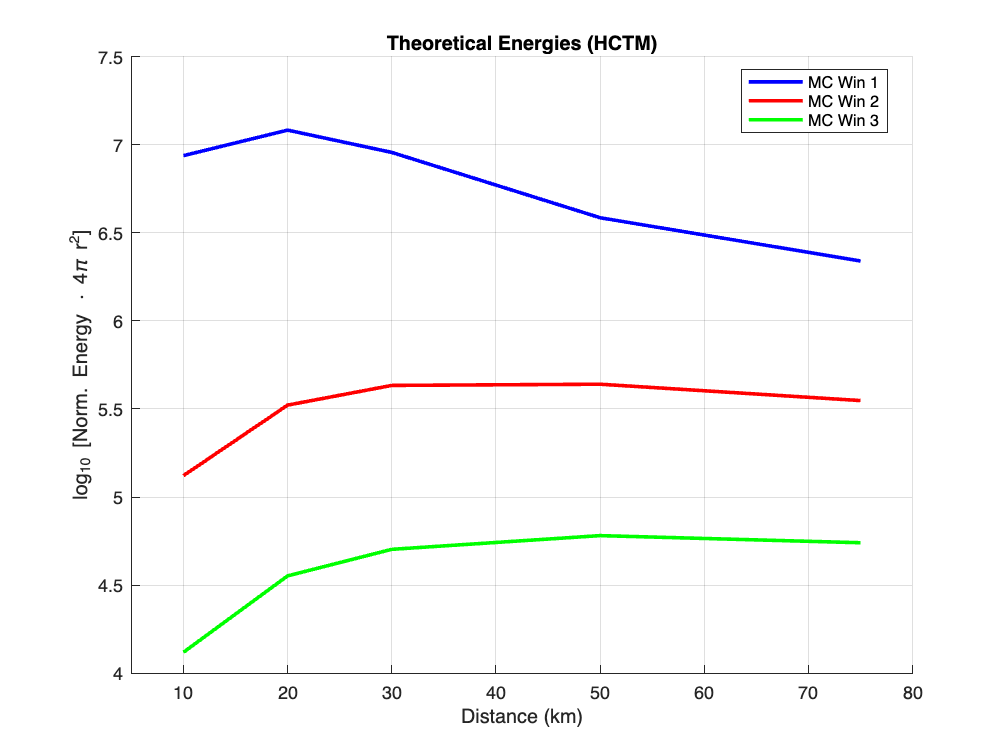

% fprintf('--- Plot Theoretical energies with observed ones ---\n');
% tW_in = 15; % Length windows
% tc_in = 50; % Strart of the coda window
% 
% % Set this flag depending on your simulation needs
% compare_with_data = false; % Change to true when you want to see Visso data
% file_mat_real = 'MLTWA_Visso_corrected.mat'; 
% 
% if compare_with_data
%     WinData = extract_windows(p, dists_vec, file_histogram, tW_in, tc_in, data_ready, target_frequency);
% else
%     % Calling with only 5 arguments: no real data will be plotted
%     WinData = extract_windows(p, dists_vec, file_histogram, tW_in, tc_in);
% end

## Phase 3: Plotting

From the histogram output we plot the energy envelopes for the chosen distances.

fprintf('--- PHASE 3: Plot Generation ---\n');

--- PHASE 3: Plot Generation ---


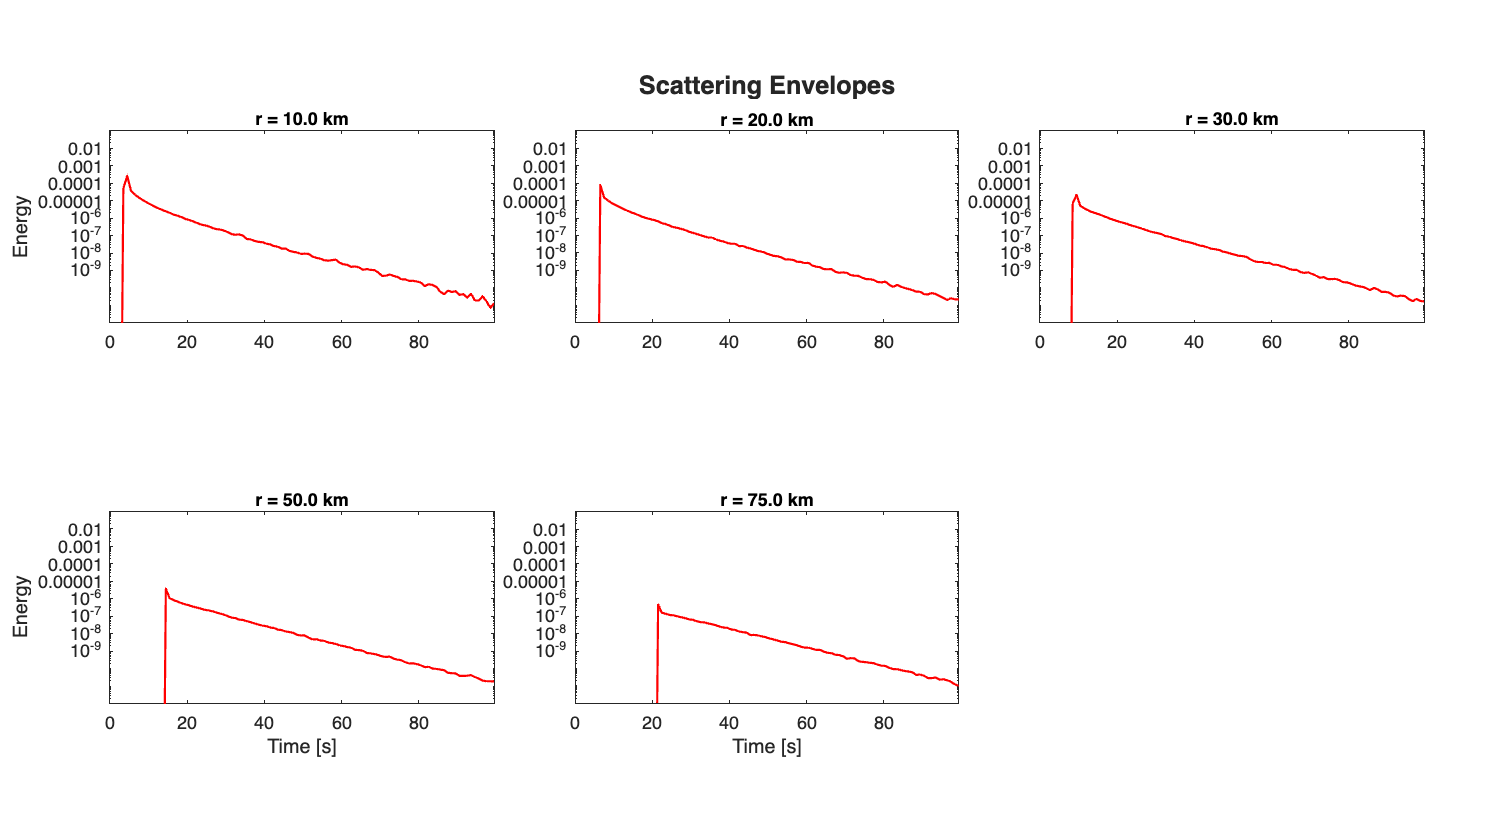

plot_envelopes(file_histogram, dists_vec);